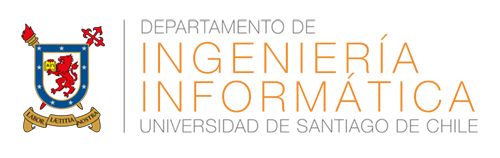

# Laboratorio 3

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# Ecuaciones en diferencia

Recordemos la forma canónica recursiva para representar un sistema lineal e invariante en el tiempo:


$$\sum_{k=0}^N a_k y[n-k] = \sum_{k=0}^M b_k x[n-k] $$


donde usualmente $a_0 = 1$. Analicemos un filtro simple [1]:


$$y[n] = x[n] + x[n-1] $$


Los coeficientes $a_k$ y $b_k$ de la ecuación en diferencia corresponden a $a_0 = 1$, $a_k = 0$ y $b_k = 1$ con $k = 1,2$. En matlab podemos utilizar la función filter para obtener la salida $y[n]$ a partir de una entrada $x[n]$. También, podemos obtener la respuesta al impulso $h[n]$ con la función impz.

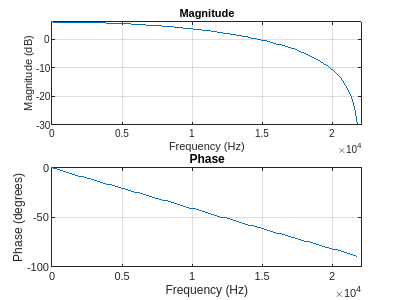

clearvars

n = -5:5;
b = [1 1];
a = 1;
x_n = n==0;
y_n = filter(b,a,x_n);
h_n = impz(b,a,n);

freqz(b,a,100,44100)

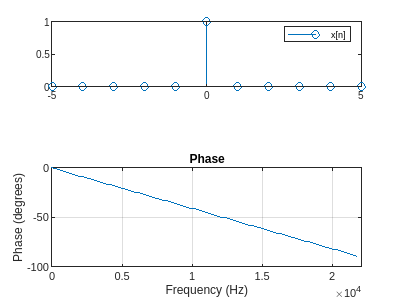


subplot(3,1,1)
stem(n,x_n)
legend('x[n]')

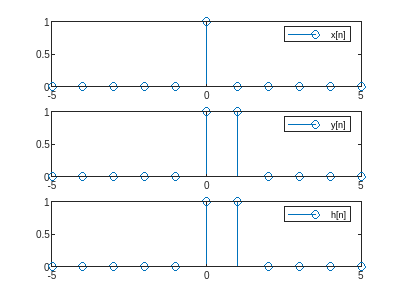

subplot(3,1,2)
stem(n,y_n)
legend('y[n]')
subplot(3,1,3)
stem(n,h_n)
legend('h[n]')

# Transformada Z

Para un sistema lineal e invariante en el tiempo. es conveniente realizar la transformada Z de la forma canónica recursiva:


$$y[n] + a_1 y[n -1] + \ldots a_N y[n-N] = b_0 x[n] + b_1 x[n-1] + \ldots + b_M x[n-M] $$


resultando en:


$$Y[z] + a_1 Y[z]z^{-1} + \ldots a_N Y[z]z^{-N} = b_0 X[z] + b_1 X[z]z^{-1} + \ldots + b_M X[z]z^{-M} $$



$$\frac{Y[z]}{X[z]} = \frac{b_0 + b_1 z^{-1} + \ldots + b_M z^{-M}}{1 + a_1 z^{-1} + \ldots + a_N z^{-N}}$$


donde $Y[z]/X[z] = H[z]$. Con esta representación, podemos obtener el grafico de polos y ceros del sistema:

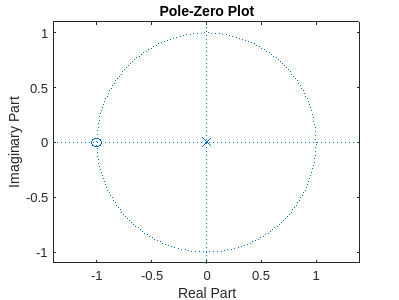

clearvars

b = [1 1];
a = 1;

figure
zplane(b,a)

# Señales reales

La función audioread nos permite leer distintos formatos de archivos y obtener su frecuencia de muestreo. Para este ejemplo, utilicemos un archivo de audio en formato WAV y apliquemos el filtro creado.

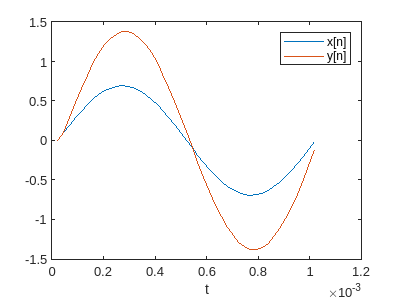

clearvars

[x_n,Fs] = audioread('1kHz_44100Hz_16bit_05sec.wav');
b = [1 1];
a = 1;
y_n = filter(b,a,x_n);

figure
N = 45;                  % aprox Fs*T muestras
plot((1:N)/Fs,x_n(1:N))  % con T = periodo 1kHz
hold on                  % T = 1/f
plot((1:N)/Fs,y_n(1:N))
xlabel('t')
legend('x[n]','y[n]','Location','NorthEast')

# Referencias

[1] Julius O. Smith III, Introduction To Digital Filters: With Audio Applications (Online) https://www.dsprelated.com/freebooks/filters/